# Statistics and Data Analysis: Linear Regression

- Two-group comparison: parametric t-test and non-parametric t-test

- Multi-group comparison: two factor ANOVA

- post hoc comparison

- linear regression

- correlation coefficent

- residuals

- regression to the mean

- multiple linear regression

## Student's T-test

You might wonder why the [T-test](https://en.wikipedia.org/wiki/Student's_t-test) is called "Student t-test"? In 1908, William Sealy Gosset, a chemist working for the Guinness brewery, developed the test as a way to monitor the chemical quality of stout. However, the company policy at Guiness did not allow for publication. So, Gosset published the work under the pseudonym 'Student'. 

The t-test is used to determine if two sets of data are significantly different from each other. Therefore, the t-test assumes normal distribution and you should be cautious if sample sizes or variances are unequal. 

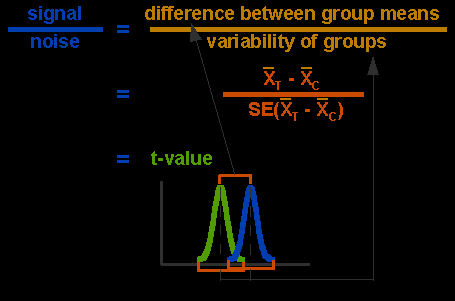

*Example study I: To test the efficacy of a drug in mice on locomotor activity. We have 2 experimental groups: drug and control. Each group contains 10 male animals. We will start to use the t-test for locomotor activity measurements between the 2 groups. First we will construct data that will show a clear effect of drug:*

n = 10; %10 subjects
mCtrl = randn(n,1); %randn, mean of 0 and variance of 1
mDrug = mCtrl + 1 + randn(n,1);

First, we will test if there are differences between the animals (*i.e*.10+10=20 total). This will be a test 'across-subject' with [unpaired data](https://en.wikipedia.org/wiki/Paired_data) for which we use a two-sample t-test:

[h,p]= ttest2(mCtrl,mDrug)

h = 1

p = 0.0476

A [paired](https://en.wikipedia.org/wiki/Paired_data) data set arises when data is collected from the same animal at different points in time, *e.g.* drug at the first time point and saline at the second time point. Therefore, our data set has an n-number of 10 total instead of 20. We will test the 'within-subject' differences using a paired t-test.

[h,p]= ttest(mCtrl,mDrug)

h = 1

p = 0.0089

For many data sets, we do not know the underlying distribution. For example, calcium imaging data involves fractional changes in fluorescence (dF/F) where most values are zero, with some large positive values. The [non-parametric test](https://en.wikipedia.org/wiki/Nonparametric_statistics) has no assumption about the underlying distribution, which means it does not assume that the data is Normal distributed. The main used non-parametric tests is the Wilcoxon rank-sum test, also known as [Mann-Whitney U test](https://en.wikipedia.org/wiki/Mann%E2%80%93Whitney_U_test), which is the *ranksum* command in MatLab. The rank-sum test is for unpaired data. 

[p,h]=ranksum(mCtrl,mDrug)

p = 0.0257

h =    1


The non-parametric test for paired data is the [Wilcoxon signed-rank ](https://en.wikipedia.org/wiki/Wilcoxon_signed-rank_test)test.

[p,~] = signrank(mCtrl,mDrug)

p = 0.0137

## ANOVA - analysis of variance

We moving from a two-group comparison (t-test )to a multi-group comparison ([ANOVA](https://en.wikipedia.org/wiki/Analysis_of_variance)). ANOVA is used to analyze the differences among group means and their associated procedures (such as "variation" among and between groups). If the variability is significantly larger in "between-group", then ANOVA will reject the null hypothesis of equality among population means. In complex biological systems, multiple experimental factors may interact to produce effects. For example, multiple drugs can be administered simultaneously, and all pairwise level combinations can be observed in a single experiment, which is more revealing than test one drug at a time. In particular, we would miss insights about synergies. 

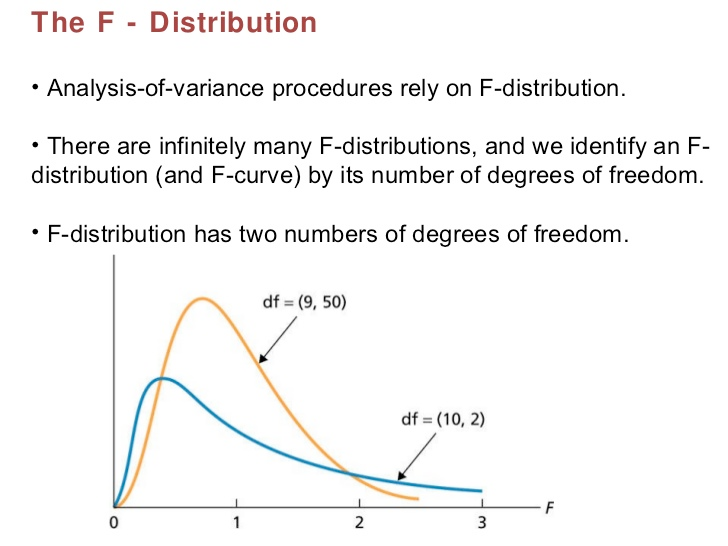

Using a t-tests with more than 2 groups would be inappropriate because we would need to perform many t-test. These t-tests will be effectively from the same population, so we would draw more than 2 samples and test the differences between their means. As this is done repeatedly from the same population, we will increase the chance of a [type I error](https://en.wikipedia.org/wiki/Type_I_and_type_II_errors). 

*Example study II:  Main effect. We will test the efficacy of a drug on mice on locomotor activity using 4 experimental groups, each contain 10 animals: male/drug, female/drug, male/control, female/control. Next to the drug effect, we will also look for the effect of sex. We will use 'complete factorial', which means that every combination is observed. First, we construct data that will show a clear effect of drug and create/use the functions "plot_effect" and "test_effect".*

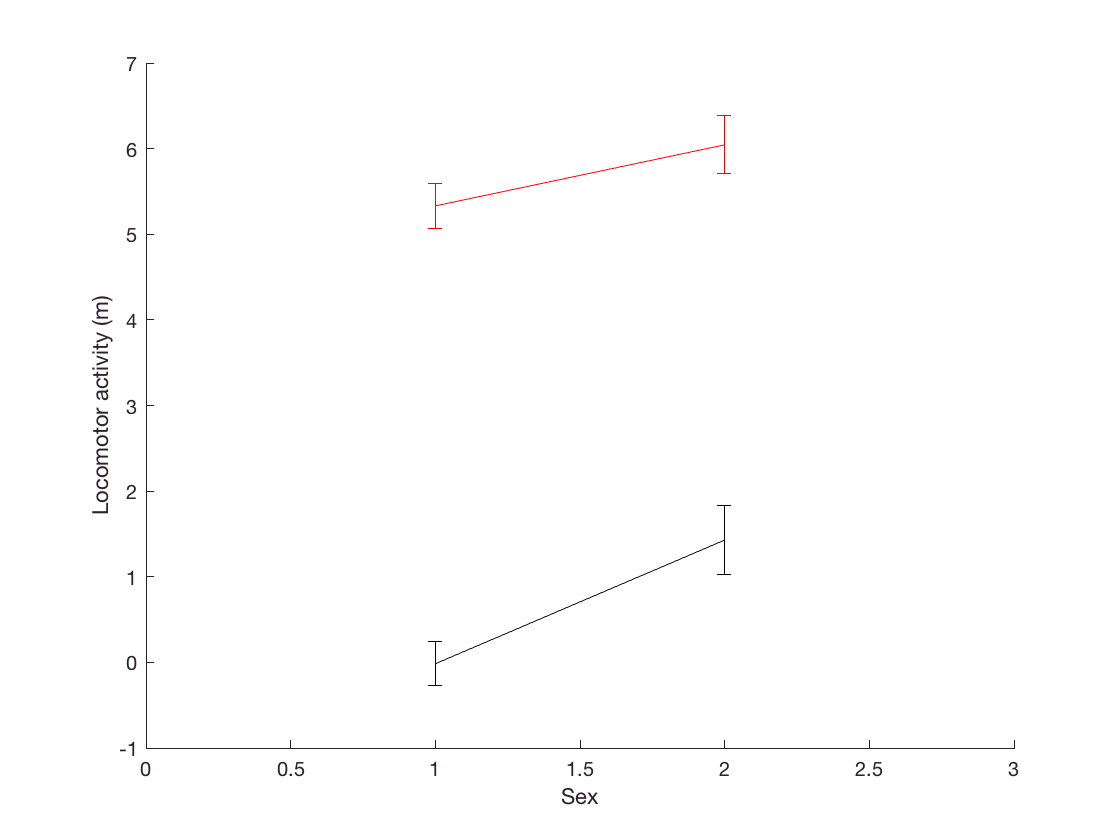

mCtrl = randn(n,1);
fCtrl = randn(n,1)+1;
mDrug = 5 + randn(n,1);
fDrug = 6 + randn(n,1);

plot_effect(mCtrl,fCtrl,mDrug,fDrug)

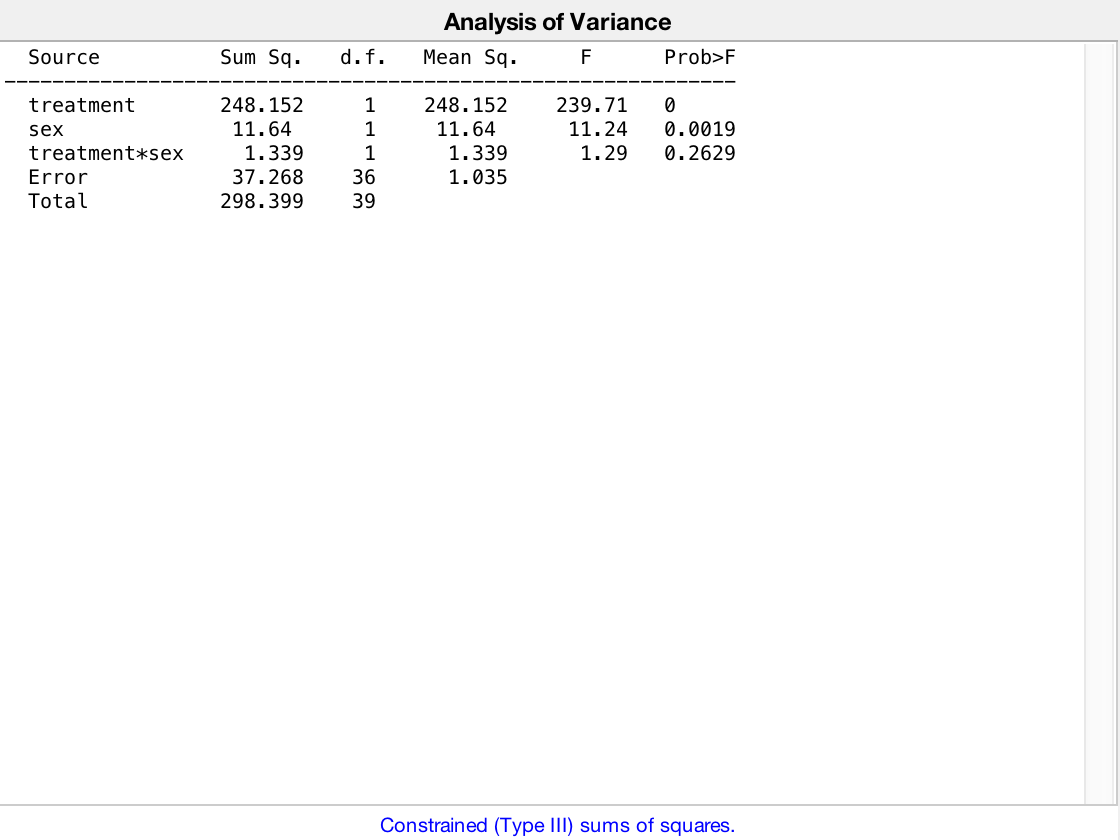

test_effect(mCtrl,fCtrl,mDrug,fDrug)

How to read the N-Way ANOVA table generated in Matlab: 

- d.f.: degree of freedom; basically group size minus 1

- F: the F test statistics, often included in papers, with subscripts to indicate (#group - 1) and (#sample - #group).

- Prob > F: the p-value

*Let's try another set of locomotor activity measurements of the 4 groups. Here we construct data with the effect of drug that also differ by sex.*

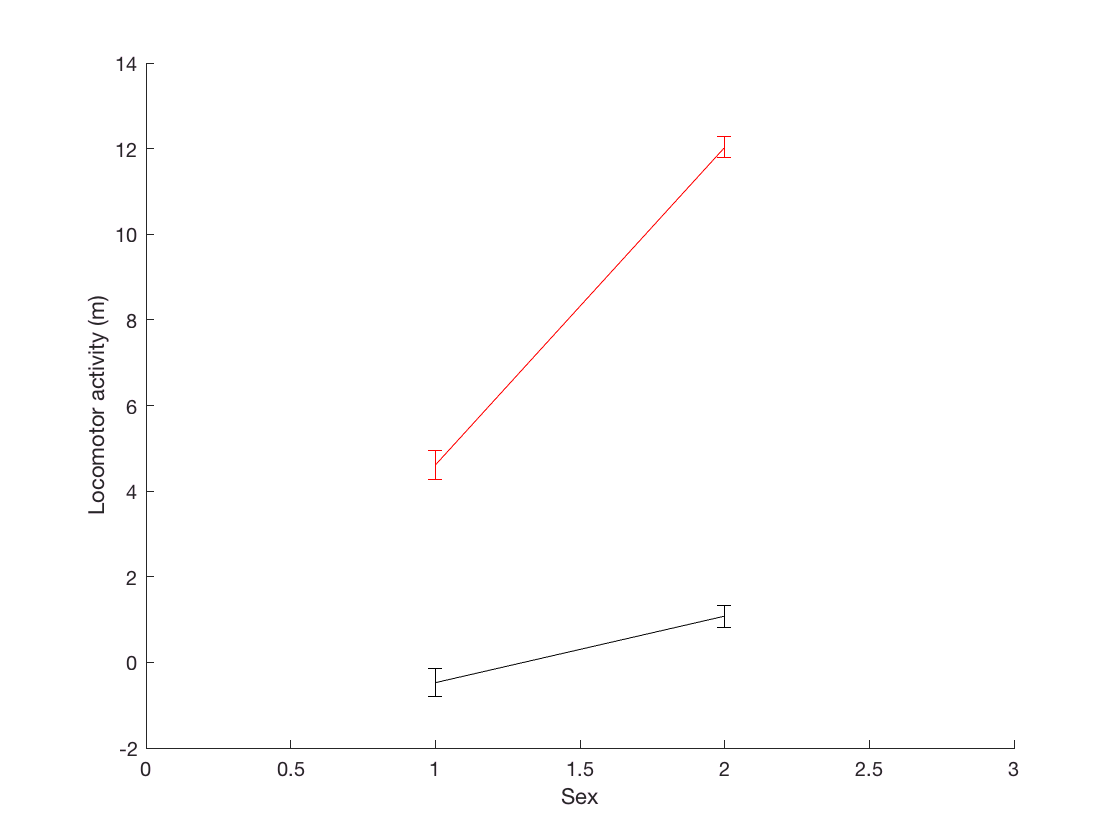

mCtrl=randn(n,1);
fCtrl=1+randn(n,1);
mDrug=5+randn(n,1);
fDrug=12+randn(n,1);

plot_effect(mCtrl, fCtrl, mDrug, fDrug);

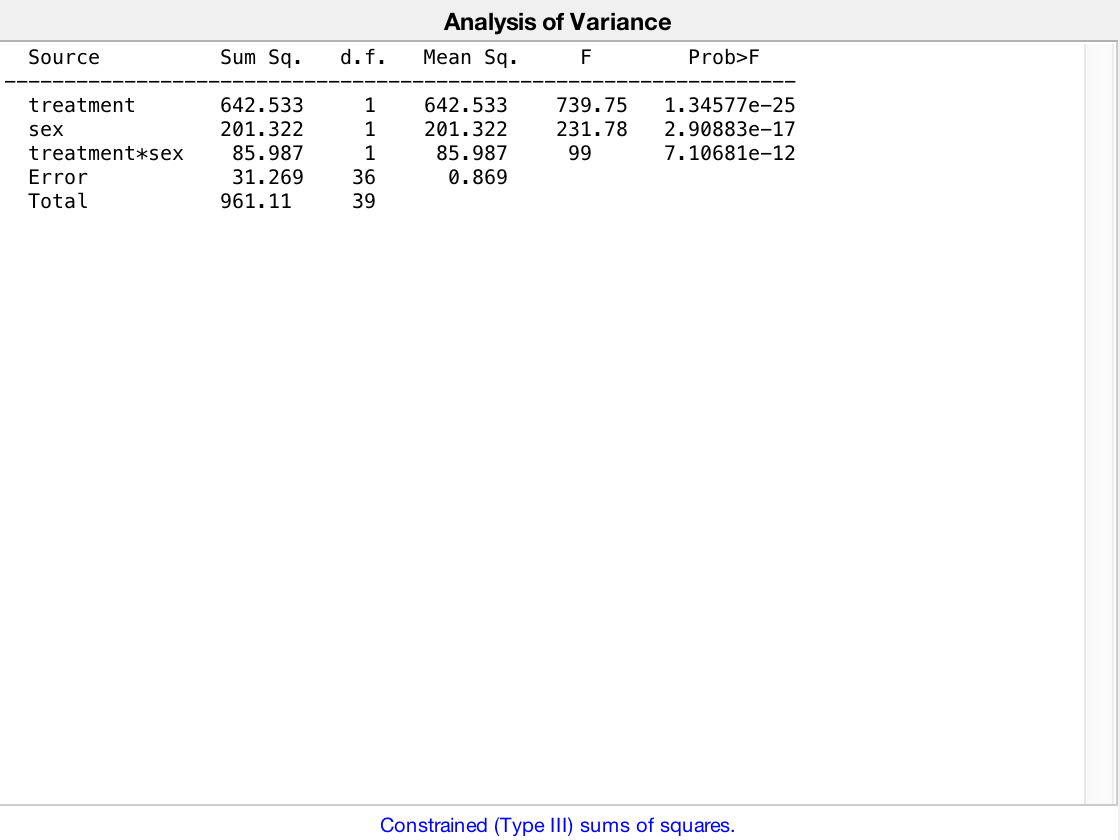

test_effect(mCtrl, fCtrl, mDrug, fDrug);

When an interaction is present, the test of significance for the main effect will be ignored.

## Interaction effect

In statistics, an [interaction](https://en.wikipedia.org/wiki/Interaction_(statistics)) may arise when considering the relationship among three or more variables, and describes a situation in which the simultaneous influence of two variables on a third is not additive. Here we discuss two types of interaction: the repeated measures and the fixed vs random effects. 

A [repeated measures ANOVA](https://statistics.laerd.com/statistical-guides/repeated-measures-anova-statistical-guide.php) is also referred to as a within-subjects ANOVA or ANOVA for correlated samples. The repeated measure detects any overall  differences between related means. For example, sometimes in ANOVA data sets there is a longitudinal grouping, *e.g.* days of treatment. The same subject is treated over multiple days and each day is associated with a data point. This design requires a repeated measures ANOVA. 

Another interaction effect is the ['Fixed' vs 'Random effects'](https://www.ma.utexas.edu/users/mks/statmistakes/fixedvsrandom.html).  A [fixed effect](https://en.wikipedia.org/wiki/Fixed_effects_model), also known as the within estimator, refers to time independent effects for each entity that are possibly correlated with the regressors. In other words, data has been gathered from all the levels of the factor that are of interest. Here sex is a fixed effect. A [random effect](https://en.wikipedia.org/wiki/Random_effects_model) assumes that the data being analysed are drawn from a hierarchy of different populations whose differences relate to that hierarchy. Therefore, the factor has many possible levels, *i.e. *interest in all possible levels. For example, site of experiment would be a random effect, a subset of all possible groupings.

*Example study III: a third set of locomotor activity measurements of the 4 groups.*

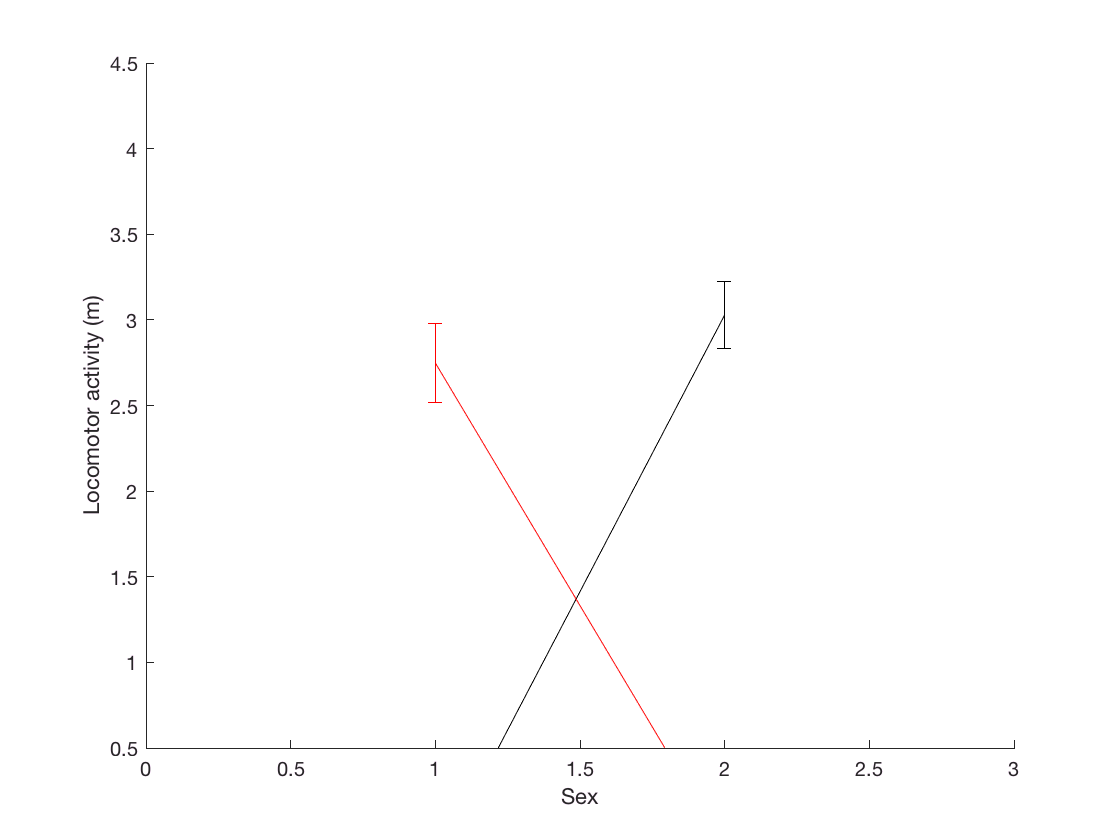

mCtrl=randn(n,1);
fCtrl=3+randn(n,1);
mDrug=3+randn(n,1);
fDrug=randn(n,1);

plot_effect(mCtrl, fCtrl, mDrug, fDrug);

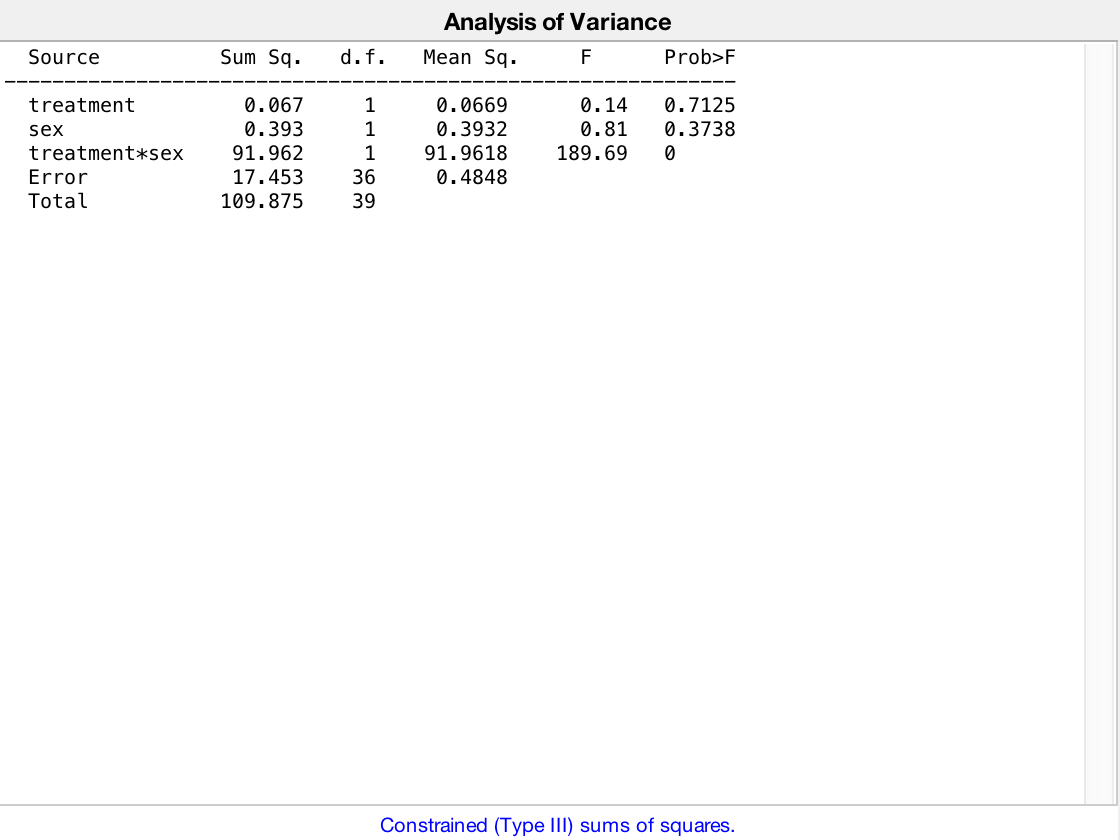

% interaction effects may mask main effects

test_effect(mCtrl, fCtrl, mDrug, fDrug);

## Post-hoc multiple comparison

When ANOVA shows an overall statistically significant difference in group means (main/interaction effect), a [post-hoc comparison test](https://en.wikipedia.org/wiki/Post_hoc_analysis) is performed to confirm where the differences occurred between groups.  The post-hoc test uses a stepwise multiple comparisons procedure to identify sample means that are significantly different from each other.

*Example study IV: We will create 1 wild-type and 3 transgenic groups, each with 10 animals, to test different mouse strains on locomotor activity.*

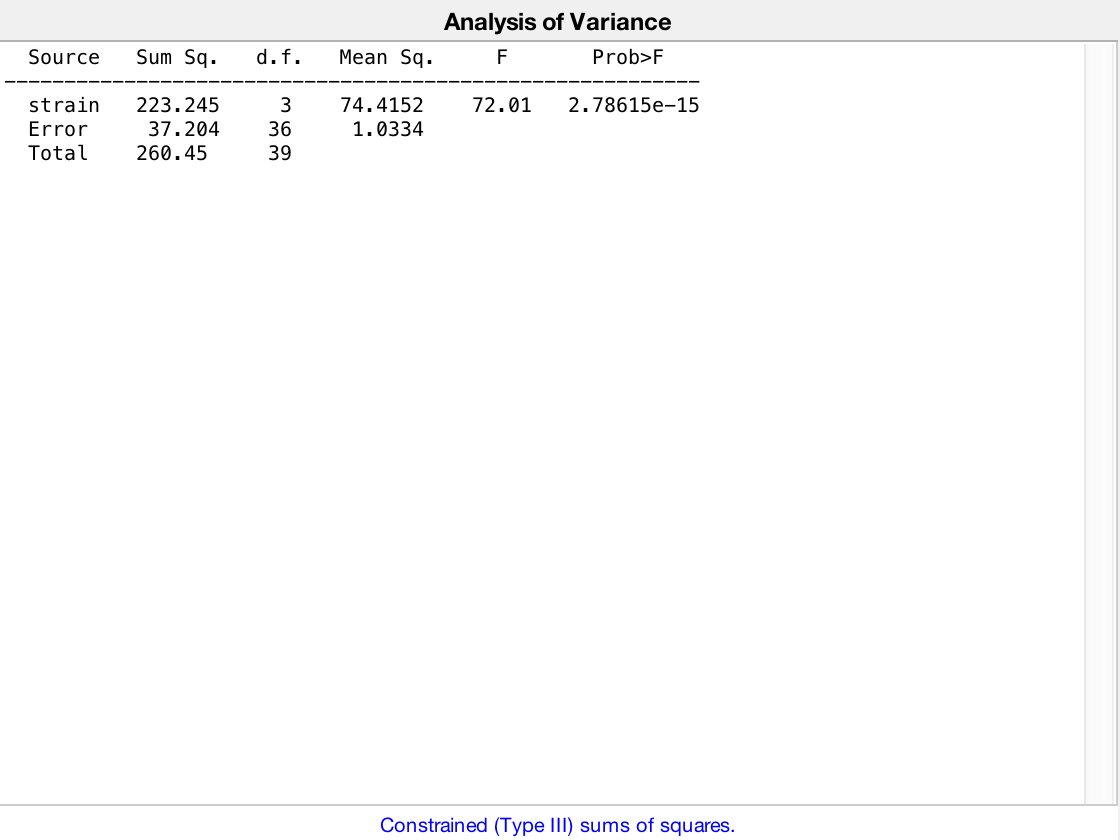

ctrl = randn(n,1);
tg1 = 0.2 + randn(n,1);
tg2 = 4 + randn(n,1);
tg3 = 6 + randn(n,1);

% run a one-way ANOVA
data = [ctrl tg1 tg2 tg3];
strain = [zeros(size(ctrl)) ones(size(tg1)) 2*ones(size(tg2)) 3*ones(size(tg2))];
[~,~,stats,~] = anovan(data(:),strain(:),'model','linear','varnames',{'strain'});

 Now, we will proceed with a 'post-hoc multiple comparison'. Note: in the plot, blue is group selected to be compared with all other groups

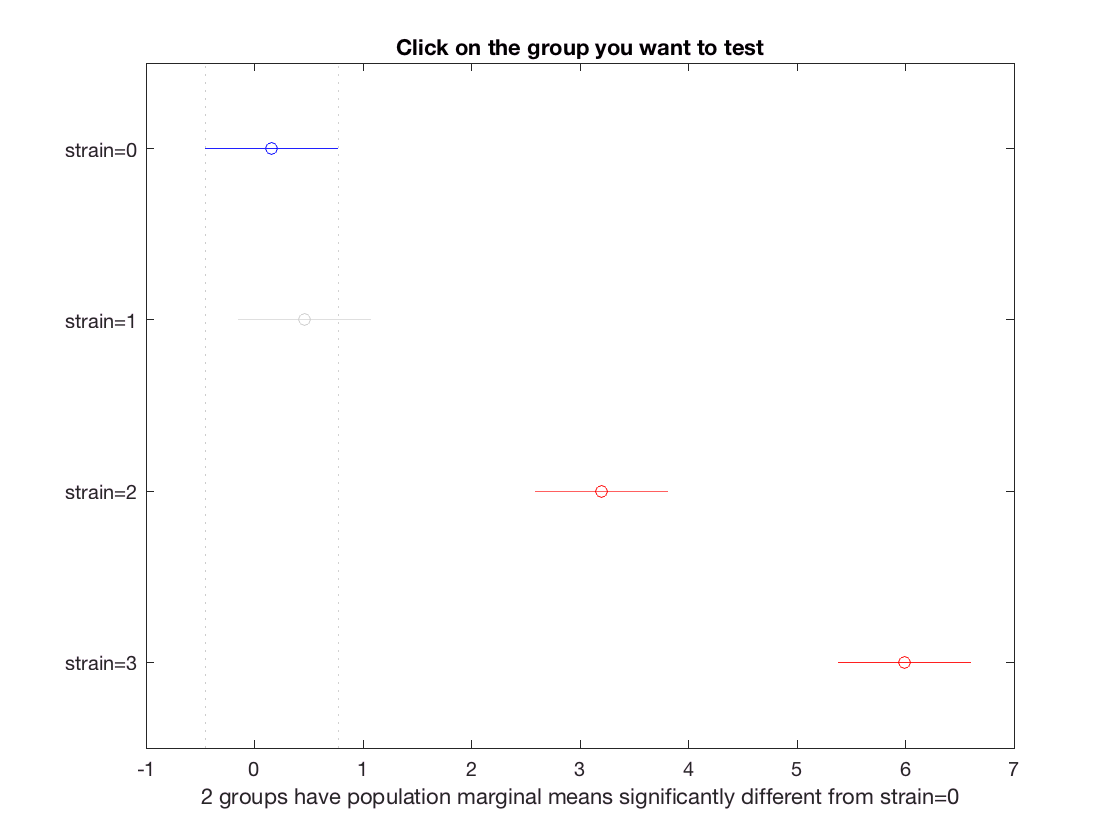

comp = multcompare(stats);

% look in the variable 'comp' to see the actual p-values
comp

comp =     1.0000    2.0000   -1.5254   -0.3010    0.9234    0.9106
    1.0000    3.0000   -4.2651   -3.0407   -1.8163    0.0000
    1.0000    4.0000   -7.0585   -5.8341   -4.6097    0.0000
    2.0000    3.0000   -3.9641   -2.7397   -1.5153    0.0000
    2.0000    4.0000   -6.7576   -5.5331   -4.3087    0.0000
    3.0000    4.0000   -4.0179   -2.7934   -1.5690    0.0000


## Power analysis

The [Power](https://en.wikipedia.org/wiki/Statistical_power) or sensitivity of a binary hypothesis test is the probability that the test correctly rejects the null hypothesis (H0) when the alternative hypothesis (H1) is true.

You can use the G-power 3.1 tool to perform Power analysis. Choose F-test for ANOVA test. 

## Correlation and Simple Linear Regression

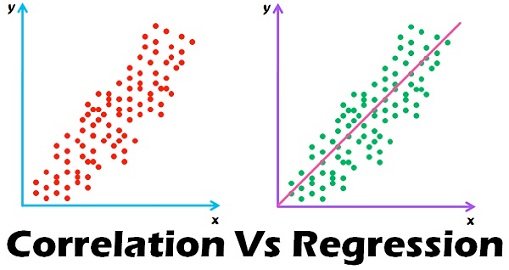

[Correlation](https://en.wikipedia.org/wiki/Correlation_and_dependence) measeures the dependence or association of a statistical relationship between two random variables or two sets of data. Caution though: [correlation is not the same as causation](http://www.edubrainstorm.com/blog/index.html)! 

[Linear regression](https://en.wikipedia.org/wiki/Linear_regression) is an approach for modeling the relationship between a scalar [dependent variable](https://en.wikipedia.org/wiki/Dependent_variable) Y and one or more [explanatory variables](https://en.wikipedia.org/wiki/Explanatory_variable) (or independent variables) denoted X. The case of one explanatory variable is called [*simple linear regression*](https://en.wikipedia.org/wiki/Simple_linear_regression). For more than one explanatory variable, the process is called *multiple linear regression*.

For both these methods, the actual values of the data is used, such as measuring the amount of drug in a system. 

*Example study V:  We will test the efficacy of a drug on mice on locomotor activity. Here we consider the amount of drug measured in blood sample. Instead of categories (drug vs no drug given to animal), we have numerical values (how much drug).*

n = 40;
drug = 5 + randn(n,1);
slope = 0.4;
activity = slope * drug + randn(n,1); %linearly related plus some noise

figure;
plot(drug,activity,'ko','MarkerSize',10);
xlabel('Drug dose (mg)'); %independent variable
ylabel('Locomotor activity (m)'); %dependent variable

Now we use a simple linear regression, or linear fit, to find the best line through our data that shows how Y varies with X. Therefore, we detemine the slope and the intercept and whether the slope and intercept are significantly different from zero.

stats = regstats(activity,drug,'linear');
stats.beta

ans =     1.2625
    0.1598


stats.tstat.pval %is the slope significantly different from zero?

ans =     0.1403
    0.3359


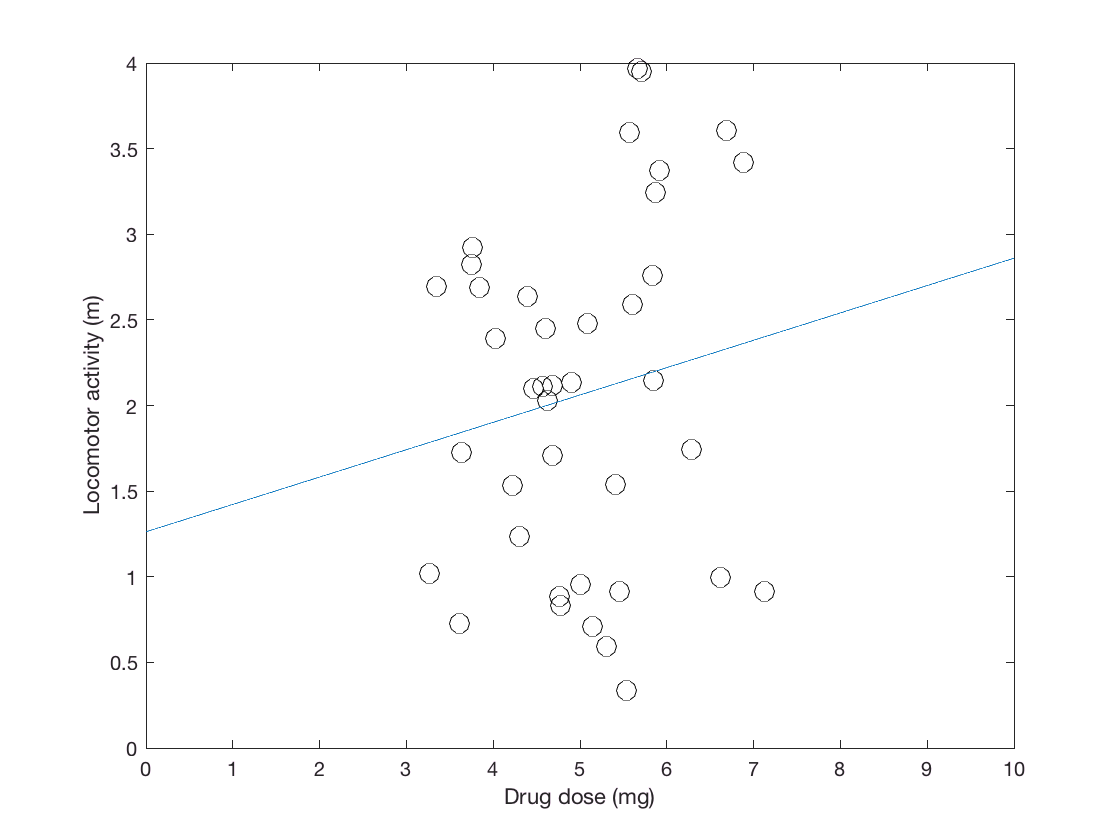

% let's plot the slope in the same figure
hold on;
x=[0:0.01:10];
plot(x,stats.beta(1)+x*stats.beta(2));

## Correlation Coefficient

The [correlation coefficient](https://en.wikipedia.org/wiki/Correlation_coefficient) is a number that quantifies a type of correlation/dependence, which means the statistical relationships between two or more values. In MatLab we use the *corr *function, which is a [Pearson](https://en.wikipedia.org/wiki/Pearson_correlation_coefficient) correlation that assumes linearity and measures linear trends, ranging from -1 to 1. The squared Pearson correlation coefficient r^2 can be interpreted as the proporation of variation in Y explained by X, for example r = 0.9 means that 81% of the variance of Y is explained by X. 

corr(drug, activity, 'type', 'Pearson')

ans = 0.1562

Another one would be [Spearman](https://en.wikipedia.org/wiki/Spearman's_rank_correlation_coefficient), which is based on rank correlation and therefore not linear.

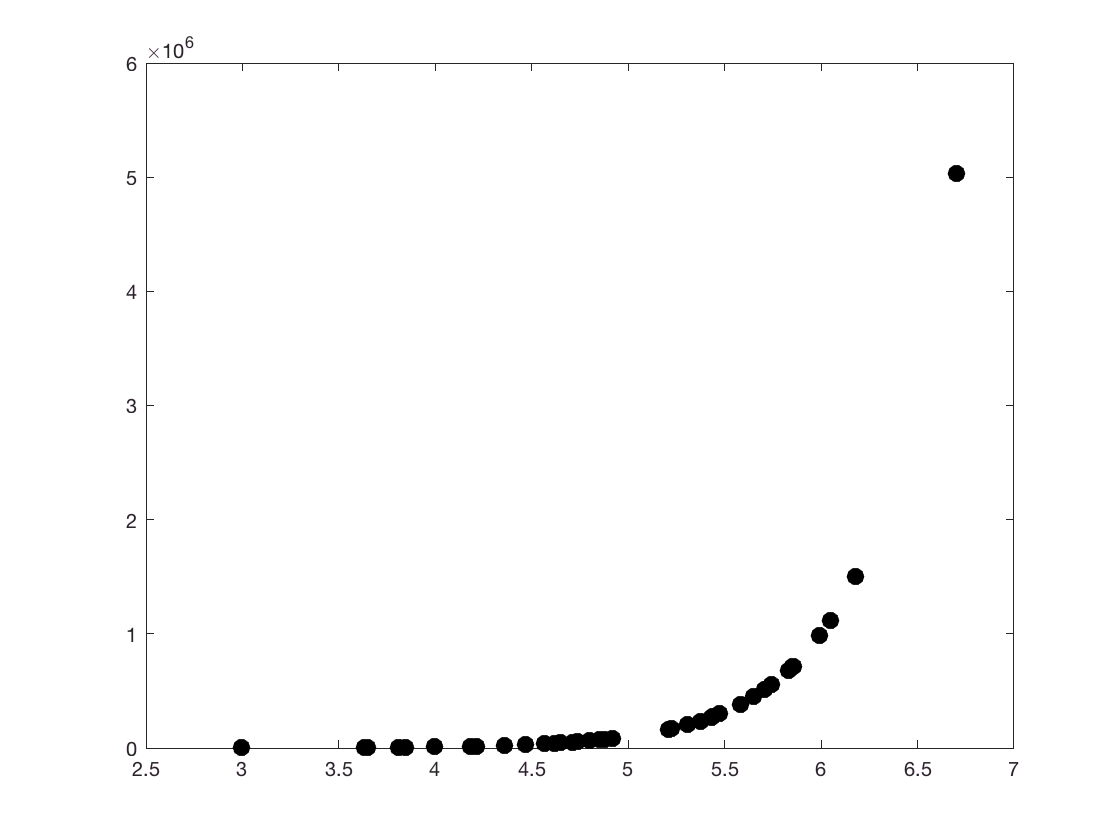

drug = 5 + randn(n,1);
activity = 10.^drug;
figure;
plot(drug,activity,'k.','MarkerSize',30);


corr(drug,activity,'type','Pearson')

ans = 0.6226


% Spearman's or rank correlation, measures increasing or decreasing trends
corr(drug,activity,'type','Spearman')

ans = 1

The correlation coefficient is sensitive to the noise in the data as well as the sample size

First we will test the effect of **noise**:

drug = 5 + randn(n,1);
slope = 0.4;

activity = slope * drug + 0.1*randn(n,1); %linearly related plus some noise
subplot(2,2,1);
plot(drug,activity,'o','MarkerSize',5);
corr(drug,activity,'type','Pearson')

ans = 0.9731


activity=slope*drug+0.5*randn(n,1); %more noise
subplot(2,2,2);
plot(drug,activity,'o','MarkerSize',5);
corr(drug,activity,'type','Pearson')

ans = 0.5295

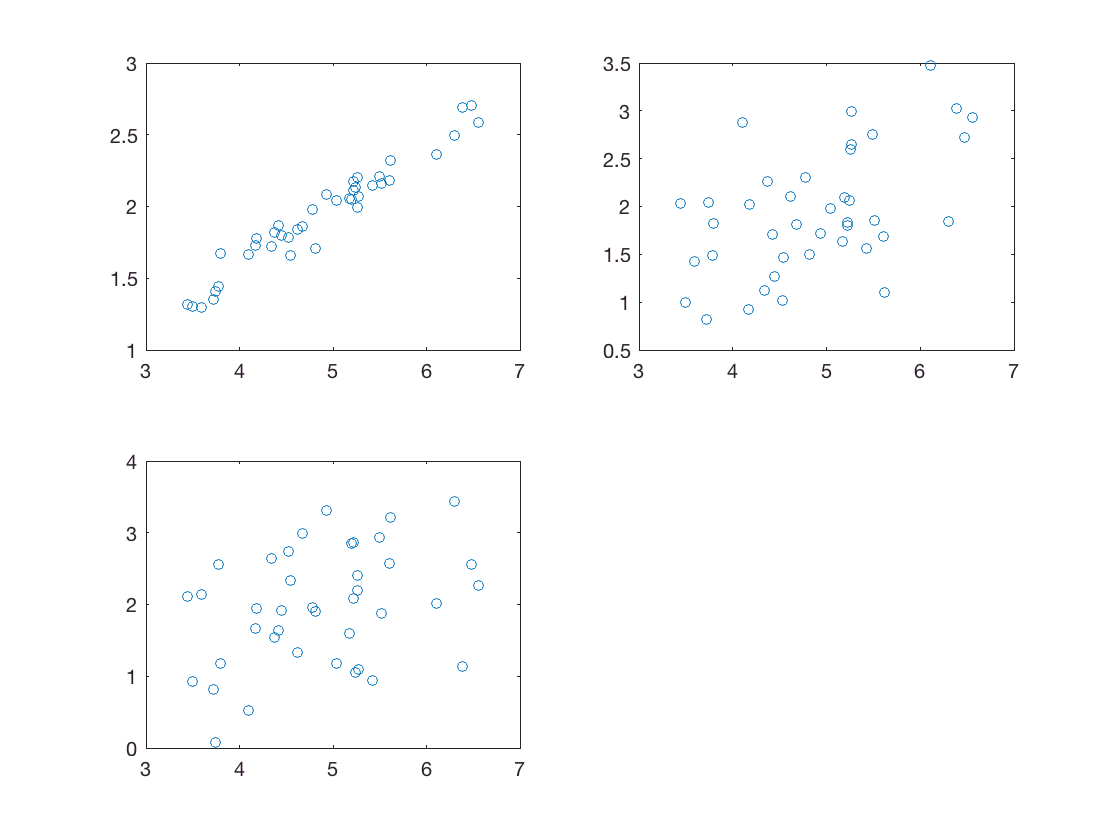


activity=slope*drug+1*randn(n,1); %a lot noise
subplot(2,2,3);
plot(drug,activity,'o','MarkerSize',5);

corr(drug,activity,'type','Pearson')

ans = 0.3518

Here we see a similar underlying trend, but with more noise the calculated correlation coefficient value is lower.

Lets try the effect of **sample size **on the correlation coefficient

n=40;
drug=5+randn(n,1);
activity=slope*drug+1*randn(n,1); %linearly related plus some noise

corr(drug,activity,'type','Pearson')

ans = 0.2786

%Re-run this several times -> with a small sample size, estimation of 
%correlation correlation can be quite variable

%given issues with noise and sample size, it is valuable to also include 
%p-value along with report of correlation coefficient
[rho,pval]=corr(drug,activity,'type','Pearson')

rho = 0.2786

pval = 0.0817

## Residuals

A [residual ](https://en.wikipedia.org/wiki/Errors_and_residuals)is a measure of how well a line fits an individual data point, which is can be used as a *regression diagnostics.* The residual of an observed value is the difference between the observed value and the *estimated* value of the quantity of interest (*i.e.* a sample mean). So, how do we know if the linear regression was appropriate? One common way is to plot the residuals. 

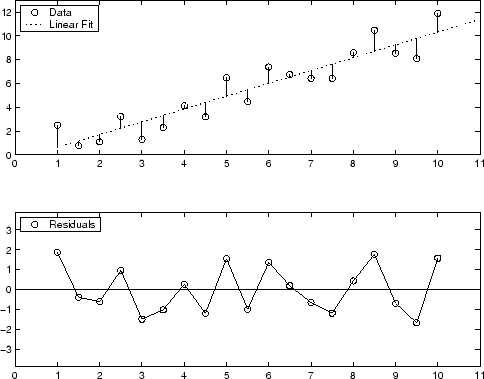

The method of [least-square errors](https://en.wikipedia.org/wiki/Least_squares) is used in regression to illustrate how linear fits are obtained, typically through minizing squared residuals. In other words, least-square errors approximate the solution of overdetermined systems, *i.e.* sets of equations in which there are more equations than unknowns. "Least squares" means that the overall solution minimizes the sum of the squares of the errors made in the results of every single equation.

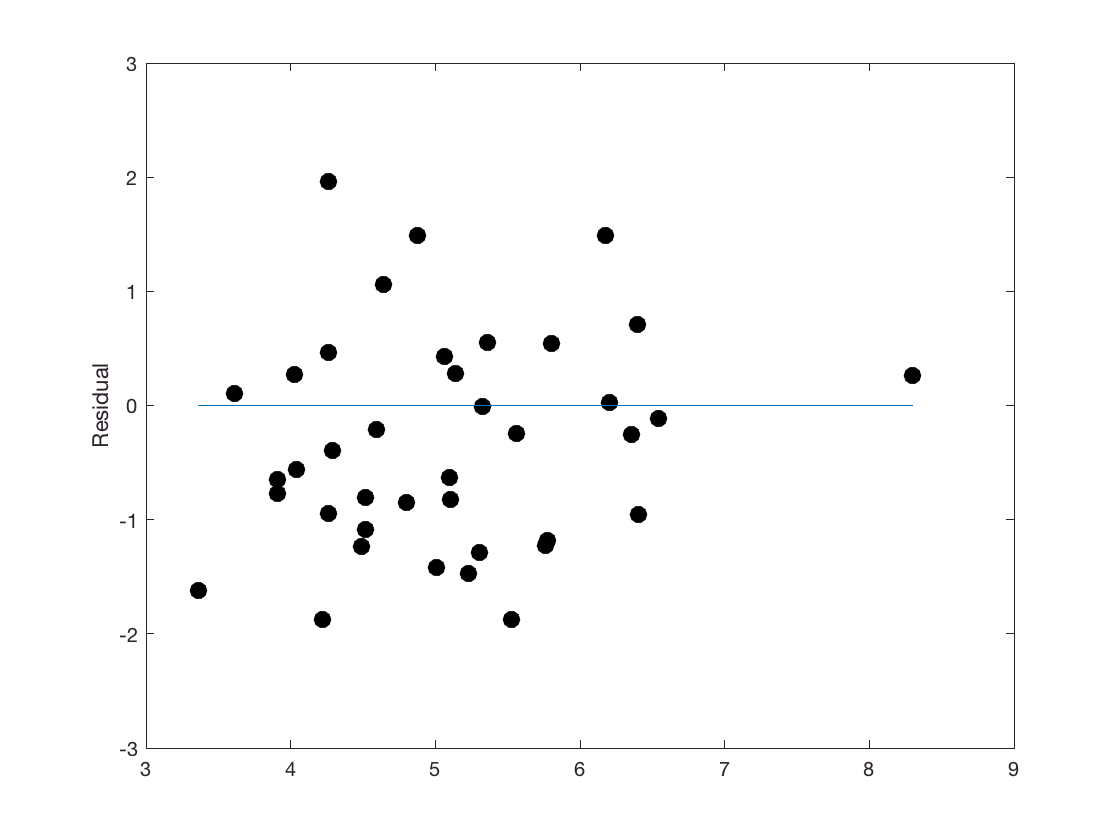

figure;
predicted = stats.beta(1) + drug*stats.beta(2);
residual = activity-predicted;
plot(drug,residual,'k.','MarkerSize',30);
hold on;
plot(drug,zeros(size(drug)));
ylabel('Residual');
ylim([-3 3]);


% the plot should show zero mean, constant spread, and no local trends

The following is an example of residuals where linear regression is inappropriate.

If instead, the relationship has an additional nonlinear term

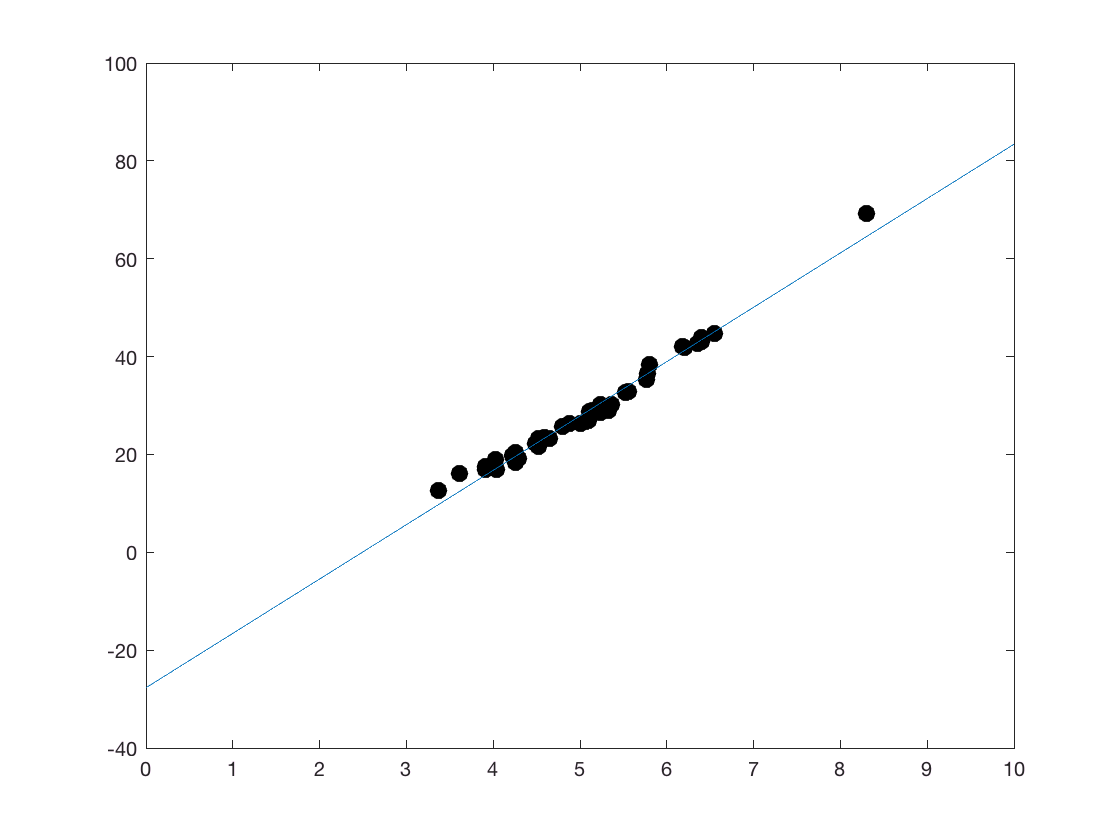

n = 40;
activity = slope * drug + randn(n,1) + drug.^2;
stats = regstats(activity,drug,'linear');

figure;
plot(drug,activity,'k.','MarkerSize',30);
hold on;
plot(x,stats.beta(1) + x*stats.beta(2));

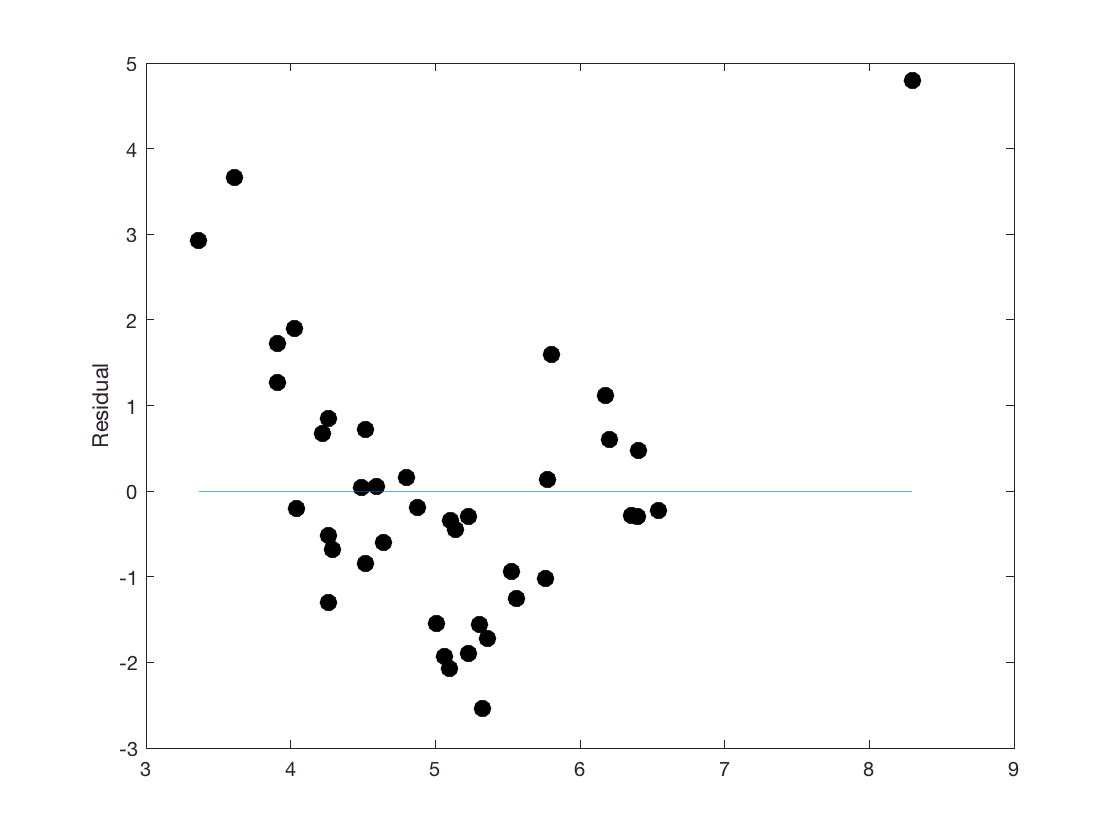


figure;
predicted = stats.beta(1) + drug*stats.beta(2);
residual = activity-predicted;
plot(drug,residual,'k.','MarkerSize',30);
hold on;
plot(drug,zeros(size(drug)));
ylabel('Residual');

## Regression to the mean

[Regression to the mean](https://en.wikipedia.org/wiki/Regression_toward_the_mean) is the phenomenon that if a variable is extreme on its first measurement, it will tend to be closer to the average on its second measurement—and if it is extreme on its second measurement, it will tend to have been closer to the average on its first. To avoid making incorrect inferences, regression toward the mean must be considered when designing scientific experiments and interpreting  data.

The following study design will try to show the effects of regression to the mean. Therefore, this is an experiment for locomotion activity in mice, in which qe pick the ones that have the lowest values for locomotion. We pick the elements that are very low and very high and regress them to see what is happening with the mean.

*Example study V: This is a problematic study design, in which we first measure locomotor activity, pick out the low-performing mice, and then treat them with drug to see if that improves the performance. This typical issue is known as regression to the mean. First, pick the low performer*

n = 40;
activity = 10 + randn(n,1);
cutoff = prctile(activity,33);
% prctile is a percentile function in which you can pick the lowest 1/3 performer
n = sum(activity<cutoff);
beforeGroup = activity(activity<cutoff);

figure; hold on;
plot(1,activity,'ko','MarkerSize',10);
plot(2,beforeGroup,'ro','MarkerSize',10);


Now we assume that the drug has no effect. The initial spread in performance is due to variability in our measurement (e.g., poor animal tracking for locomotor activity).

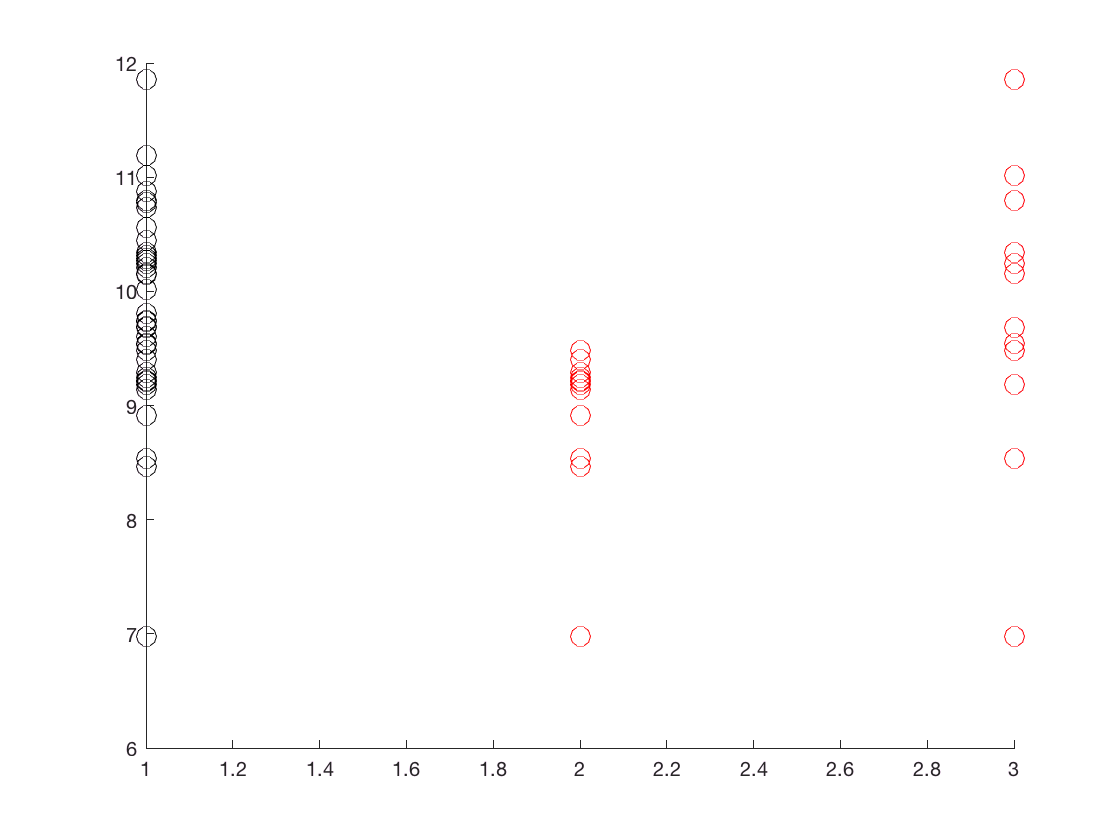

afterGroup = randsample(activity,n);
plot(3,afterGroup,'ro','MarkerSize',10);


% compare before to after, within subject: use paired t-test
[~,p]=ttest(beforeGroup,afterGroup)

p = 0.0755

The danger of this procedure is to arbitrarily cut the initial cohort of animals into low- and high-performing groups, even though there is no evidence to do so; that is, the distribution is Normal, not bimodal. This kind of regression to the mean could be an explanation for placebo effect: people who seek treatment when they are very sick tend to 'regress to the mean', regardless of whether they receive treatment or placebo. 

## Multiple Linear Regression

As mentioned in the explanation of linear regression, [multiple linear regression](http://www.statisticssolutions.com/what-is-multiple-linear-regression/) is an approach for modeling the relationship between the dependent variable Y and multiple explanatory variables X_n.

The linear regression equation is:


$$y = a + bx + \epsilon$$


Therefore, the multiple linear regression has an additional X-terms and an interaction term:


$$y = b_0 + b_1 x_1 + b_2 x_2 + ... + b_px_p + \epsilon$$


back to *Example study III: a set of locomotor activity measurements in the 4 groups*: drug/control, M/F

n = 10;
mCtrl = randn(n,1); 
fCtrl = 1 + randn(n,1);
mDrug = 5 + randn(n,1);
fDrug = 6 + randn(n,1);
data = [mCtrl; fCtrl; mDrug; fDrug];

%fit the multiple linear regression equation
factorDrug = [zeros(n,1); zeros(n,1); ones(n,1); ones(n,1)];
factorSex = [zeros(n,1); ones(n,1); zeros(n,1); ones(n,1)];
factors = [factorDrug factorSex];

%terms in the equation: 0 0 is intercept indicated by a_0, 1 0 is Drug, 0 1 is Sex, and 1 1 is the interaction
terms = [[0 0]; [1 0]; [0 1]; [1 1]];
    
stats = regstats(data,factors,terms);

%the fitted coefficients and p-values
stats.beta

ans =     0.1460
    4.6729
    0.1542
    0.4918


stats.tstat.pval % you read this in the order: first number is intercept, second one the Drug, third one the Sex, and fourth is interaction

ans =     0.6690
    0.0000
    0.7495
    0.4726


Similar p-values obtained by MLR and two-factor ANOVA

n = 1000; % increase the sample size
mCtrl = randn(n,1); 
fCtrl = 1 + randn(n,1);
mDrug = 5 + randn(n,1);
fDrug = 6 + randn(n,1);
data = [mCtrl; fCtrl; mDrug; fDrug];

factorDrug = [zeros(n,1); zeros(n,1); ones(n,1); ones(n,1)];
factorSex = [zeros(n,1); ones(n,1); zeros(n,1); ones(n,1)];
factors = [factorDrug factorSex];

stats = regstats(data,factors,terms);
stats.tstat.pval

ans =     0.2260
         0
    0.0000
    0.6332


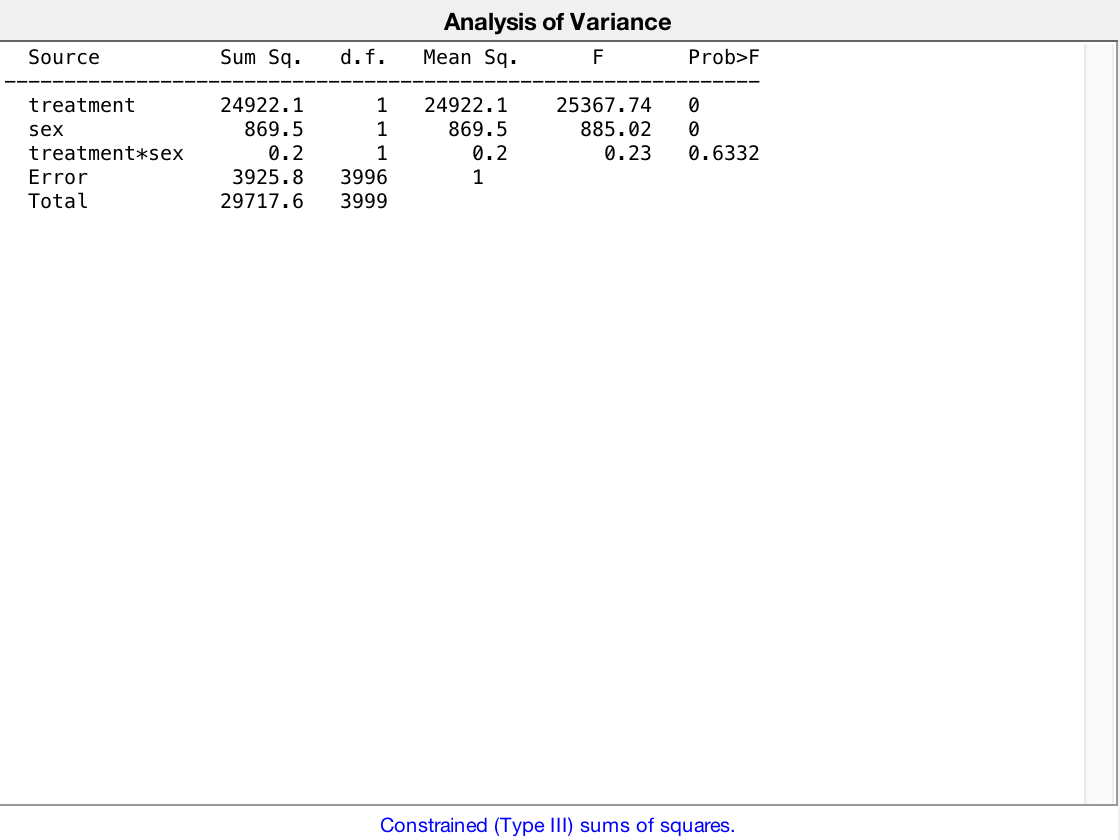

test_effect(mCtrl, fCtrl, mDrug, fDrug);